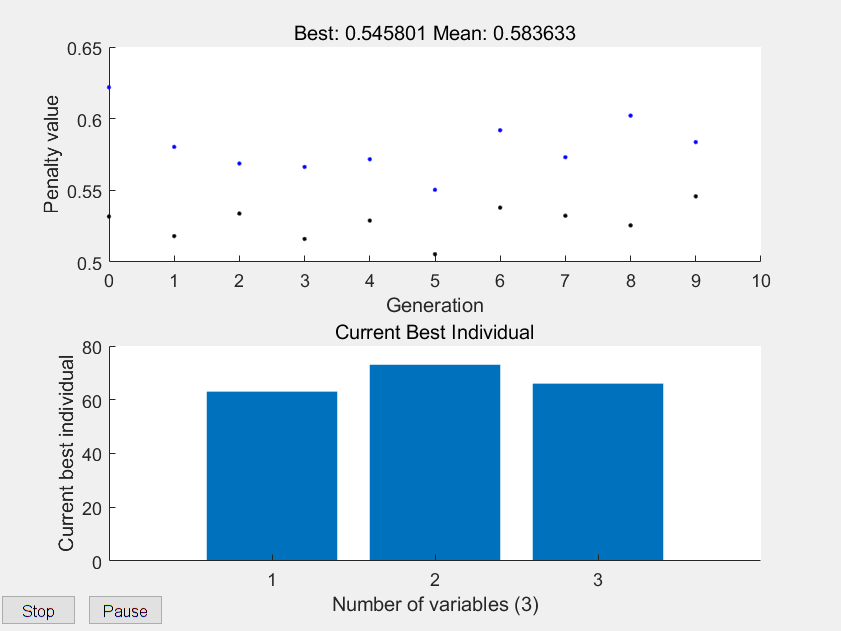

错误使用 trainNetwork
Encountered unexpected error during CUDA execution. The CUDA error was:
CUDA_ERROR_LAUNCH_FAILED

出错 adaptLSTM (第 60 行)
    net = trainNetwork(XTrain,YTrain,layers,options);

出错 gaLSTM>@(X)adaptLSTM(X,inputs,outputs) (<a href="matlab: opentoline('D:\YY\OneDrive - sjtu.edu.cn\上海交大\空间误差\智能主轴\VSS_C01\C01_DT2\gaLSTM.mlx',12,0)">第 12 行</a

index=3;
IntCon = 1:index; 
% LB=ones(1,22)*-4;
% UB=ones(1,22)*4;
LB=[10,10,10];
UB=[90,90,90];


options = optimoptions('ga','PlotFcn', ["gaplotbestf","gaplotbestindiv"],'UseParallel', true,'PopulationSize', 8,'Generations', 10);                     
% X=1:nVars;
tic
[X,fval] = ga(@(X)adaptLSTM(X,inputs,outputs),index,[],[],[],[],LB,UB,[],IntCon, options);

toc